# Validazione Closed-Loop

clear; close all; clc;

Opzione per evitare la molteplicità di 360° nella fase nei diagrammi di Bode

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

## Definizione sistema controllato

Creazione sistema e salvataggio tempo di campionamento

model_initialization;

Accelerazione massima e Rest Time

cs.setMaxAcceleration(15);
cs.setRestTime(0.1);

*Directory* per salvataggio o caricamento **dati di simulazione (validazione)**

simulation.author = 'CL_M';     Nprova = 22;
simulationName = strcat(simulation.author,'_simulation_',num2str(Nprova));
simulationDirectory = strcat('.\simulations\validation\data\',simulationName);
simFigDirectory = strcat('.\simulations\validation\figures\',simulationName);

*Directory* per caricamento **modello identificato**

simulation.author = 'CL_M';     Nprova = 22;
modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel_ID = strcat('.\estimated_models\data\',modelName);
load(directoryModel_ID)

*Directory* per salvataggio **modello validato**

simulation.author = 'CL_M';     Nprova = 22;
modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel_VAL = strcat('.\validated_models\data\',modelName);
modelFigDirectory = strcat('.\validated_models\figures\',modelName);

## Definizione segnale eccitante

## Definizione segnale eccitante e riferimento per il controllore

### Parametri

Definizione dei parametri che possono essere tarati per variare il segnale eccitante.

- Calcoliamo la **massima pulsazione ammissibile** per il segnale. Deve essere al massimo la metà della pulsazione di campionamento al fine di evitare fenomeni di *aliasing* (*Teorema di Shannon*).

- Estraiamo inoltre dal sistema la **massima coppia** che ciascun motore può erogare.

- Scegliamo un **segnale eccitante di tipo multisinusoidale** per introdurre variabilità rispetto ai dati di identificazione.

w_max = pi/st           % rad/s     (Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts)

w_max = 3.1416e+03

umax = system.getUMax   % Nm

umax =    150
   150


Multisinusoidi

w0_sin = 10; w1_sin = w_max;       % pacco di sinusoidi su tutto il range frequenziale
w0b_sin = 50; w1b_sin = 300;     % sinusoidi concentrate nella zona della risonanza
ampiezza_sin = 90;
num_sin = 30;       % numero sinusoidi (principali)
numb_sin = 30;      % numero sinusoidi (secondarie)

Portante

w_portante=w0_sin/20;
ampiezza_portante=50;
T_portante=2*pi/w_portante;

durata_simulazione = 1.1*T_portante; % secondi

### Portante

Definizione del segnale portante, che ha la funzione di fornire un segnale eccitante che permetta di evitare eccessivi attraversamenti dello zero per il segnale di velocità.

t = (0:st:durata_simulazione)';
portante = ampiezza_portante*sin(w_portante*t);

### Multisinusoidi

Il vettore delle sinusoidi è composto da due pacchi di sinusoidi

omega=sort([logspace(log10(w0_sin),log10(w1_sin),num_sin)' ; ...
            logspace(log10(w0b_sin),log10(w1b_sin),numb_sin)']);

omega=round(omega/w_portante)*w_portante;   % arrotondamento per avere le omega multiple della portante
omega=unique(omega);                        % eliminazione duplicati

Creazione segnale come somma di sinusoidi **sfasate** e **con ampiezza diversa** (massima variabilità possibile per la validazione)

multisine_signal=zeros(length(t),1);
for idx=1:length(omega)
    fase=rand*2*pi;
    ampiezza_relativa=0.5*ampiezza_sin*(1+rand); % ampiezze random tra ampiezza_sin/2 e ampiezza_sin
    coeff_sin=sin(fase)*ampiezza_relativa; coeff_cos=cos(fase)*ampiezza_relativa;
    multisine_signal=multisine_signal+coeff_cos*sin(omega(idx)*t)+coeff_sin*cos(omega(idx)*t); % sin(alpha+beta) = sin(alpha)cos(beta)+cos(alpha)sin(beta)
end

% Scalatura per la massima ampiezza
multisine_signal=multisine_signal/max(multisine_signal)*ampiezza_sin;

### Somma dei segnali

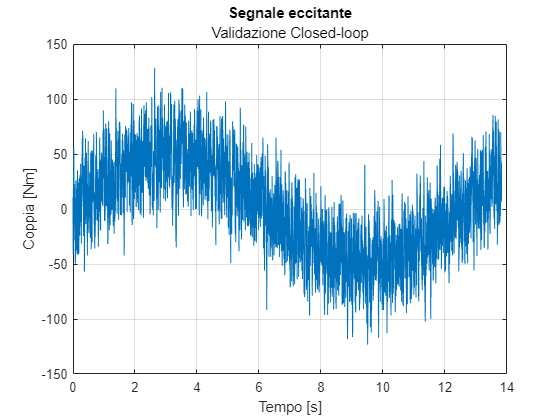

input_signal = portante+multisine_signal;

fig_inputSignal = figure;
plot(t,input_signal);
xlabel('Tempo [s]'); ylabel('Coppia [Nm]'); title('Segnale eccitante'); subtitle('Validazione Closed-loop'); grid on;

% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'.\presentation\identification\segnale_eccitante_val_CL.emf')

### Segnale di riferimento

Nullo per entrambi i giunti.

reference = zeros(length(t),system.getOutputNumber);

## Selezione sottosistemi di cui eseguire la validazione

Il segnale eccitante viene iniettato solo nei giunti la cui *checkbox* è spuntata.

joint1 = false;    joint2 = true;

if joint1 && ~joint2
    control_action = [input_signal zeros(length(input_signal),1)];

elseif joint2 && ~joint1
    control_action = [zeros(length(input_signal),1) input_signal];

elseif joint1 && joint2
    control_action = [input_signal input_signal];
    warning('Eccitare un giunto alla volta per una corretta validazione.')

else
    error('Selezionare almeno un giunto.')
end

### Calcolo durata indicativa della simulazione

durata_teorica = seconds(durata_simulazione); % debug
durata_teorica.Format = 'hh:mm:ss';
display(durata_teorica)

durata_teorica = duration
   00:00:13


sample_computation_time = 0.015; % stimato empiricamente su 100 run
durata_reale = seconds(length(t)*sample_computation_time);
durata_reale.Format = 'hh:mm:ss';
display(durata_reale)

durata_reale = duration
   00:03:27


## Controllore

Un **controllore di tipo PD**, tarato in modo poco aggressivo, permette di seguire il riferimento nullo di posizione. I parametri riferiti al **giunto in fase di validazione** saranno *tarati in modo molto blando*, affinchè il link possa comunque oscillare in una maggiore porzione dello spazio di lavoro, mentre **l'altro giunto** è tenuto nell'intorno della posizione di zero grazie ad una *taratura più aggressiva*.

if (joint1)
    Kp_values =  [1 1000];    Kv_values =  [5 50];

else % joint2
    Kp_values =  [1000 10];    Kv_values =  [50 0.5];
end

controller = SimpleScaraController(st,Kp_values,Kv_values);
cs.setController(controller);

## Simulazione sistema

checkSimulation = true;    checkLoadingData = false;

if checkSimulation && ~checkLoadingData

    f = waitbar(0,'0','Name','Simulazione - Validazione',...
                'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
    setappdata(f,'canceling',0);

%     execution_time = zeros(length(t),1); % debug

    cs.initialize % SCARA riposizionato nella configurazione di riposo iniziale

    for idx=1:length(t)
        % tic
        
        % Bottone Cancel per arrestare la simulazione senza eliminare i dati parziali
        if getappdata(f,'canceling')
            break
        end
        
        % step: simulazione sistema in anello chiuso
        % PARAMETRI
        % ingresso 1: riferimento
        % ingresso 2: azione sul carico come segnale eccitante (a valle del controllore)
        [process_output(idx,:),control_action(idx,:),tt(idx,1)]=cs.step(reference(idx,:)',control_action(idx,:)'); 

        % Aggiornamento waitbar
        percent_progress = idx/length(t)*100;
        waitbar(percent_progress/100,f,sprintf('%.2f %%',percent_progress))

        % execution_time(idx) = toc; % debug
    end

    beep

    delete(f)

%     disp('Tempo di esecuzione medio di una singola simulazione')
%     mean_execution_time = mean(execution_time) % debug

elseif checkLoadingData && ~checkSimulation
    load(simulationDirectory);

else
    error('Selezionare una delle due opzioni.')
end

## Calcolo funzione di trasferimento coppia-velocità

Calcolo e diagramma di Bode della risposta in frequenza. Le frequenze iniziali e finali per i segnali eccitanti sono indicate da linee verticali.

### Giunto 1

if (joint1)    
    % calcolo coefficienti di Fourier di ingresso e uscita
    control_action_coeff_joint1 = fourierCoefficients(tt,control_action(1:length(tt),1),w_portante,omega);
    process_output_coeff_joint1 = fourierCoefficients(tt,process_output(:,3),w_portante,omega);
    
    % Y(j*omega)/U(j*omega) -> RISPOSTA IN FREQUENZA SPERIMENTALE
    freq_resp_valid_joint1 = idfrd(process_output_coeff_joint1./control_action_coeff_joint1,omega,st);
    freq_resp_valid_joint1.OutputName = 'vel1'; freq_resp_valid_joint1.InputName = 'torque1';

    fig_j1 = figure;
    bode(freq_resp_ident_joint1,'.-b',bode_opts)
    grid on
    hold on
    bode(freq_resp_valid_joint1,'.-r',bode_opts)
    plot(w0_sin*[1 1],ylim,'--r'); plot(w1_sin*[1 1],ylim,'--r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    hold off
    legend('Identificazione','Validazione','Location','southoutside','Orientation','horizontal')
    
    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Funzione di trasferimento sperimentale - Giunto 1';

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_valid_joint1.emf')
end

### Giunto 2

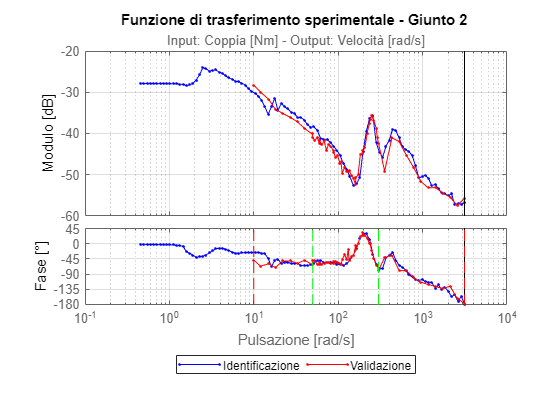

if (joint2)
    % calcolo coefficienti di Fourier di ingresso e uscita
    control_action_coeff_joint2 = fourierCoefficients(tt,control_action(1:length(tt),2),w_portante,omega);
    process_output_coeff_joint2 = fourierCoefficients(tt,process_output(:,4),w_portante,omega);
    
    % Y(j*omega)/U(j*omega) -> RISPOSTA IN FREQUENZA SPERIMENTALE
    freq_resp_valid_joint2 = idfrd(process_output_coeff_joint2./control_action_coeff_joint2,omega,st);
    freq_resp_valid_joint2.OutputName = 'vel2'; freq_resp_valid_joint2.InputName = 'torque2';

    fig_j2 = figure;
    bode(freq_resp_ident_joint2,'.-b',bode_opts)
    grid on
    hold on
    bode(freq_resp_valid_joint2,'.-r',bode_opts)
    plot(w0_sin*[1 1],ylim,'--r'); plot(w1_sin*[1 1],ylim,'--r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    hold off
    legend('Identificazione','Validazione','Location','southoutside','Orientation','horizontal')

    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Funzione di trasferimento sperimentale - Giunto 2';

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_valid_joint2.emf')
end

## Grafico dei risultati

% system.getInputName
% system.getOutputName
pos1=process_output(:,1); pos2=process_output(:,2);
vel1=process_output(:,3); vel2=process_output(:,4);
tau1=control_action(:,1); tau2=control_action(:,2);

Saturazione dei samples di coppia effettivamente applicati durante la simulazione (anche in caso questa sia stata arrestata prima del suo completamento)

actual_tau1 = min(max(tau1(1:length(tt)),-umax(1)),umax(1));
actual_tau2 = min(max(tau2(1:length(tt)),-umax(2)),umax(2));

Plot dei segnali su assi con uguale scala per i due giunti, in modo da verificare l'entità della risposta al segnale eccitante e l'azione del controllore sul giunto non eccitato.

fig_res = figure;
tl = tiledlayout(3,2);

% Posizione
nexttile; plot(tt,pos1); title('Giunto 1');
grid on; xlabel('Tempo [s]'); ylabel('Posizione [rad]'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])

nexttile; plot(tt,pos2); title('Giunto 2');
grid on; xlabel('Tempo [s]'); ylabel('Posizione [rad]'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])

% Velocità
nexttile; plot(tt,vel1); title('Giunto 1'); 
grid on; xlabel('Tempo [s]'); ylabel('Velocità [rad/s]'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])

nexttile; plot(tt,vel2); title('Giunto 2');
grid on; xlabel('Tempo [s]'); ylabel('Velocità [rad/s]'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])

% Coppia
nexttile; plot(tt,actual_tau1); title('Giunto 1');
grid on; xlabel('Tempo [s]'); ylabel('Coppia [Nm]');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

nexttile; plot(tt,actual_tau2);  title('Giunto 2');
grid on; xlabel('Tempo [s]'); ylabel('Coppia [Nm]');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

title(tl,'Segnale eccitante e risposta del sistema')

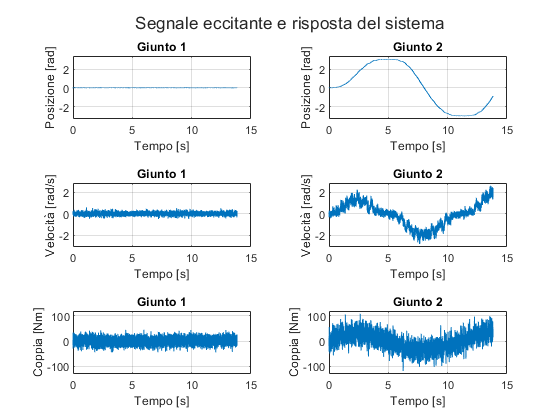

% Salvataggio della figura
set(gcf,'renderer','painters')
exportgraphics(gcf,'.\presentation\identification\segnali_val_CL.emf')

## Salvataggio simulazione

if checkSimulation
    % Salvataggio della simulazione
    simulation.description = '2xmultisin + portante - j1';
    simulation.w0_sin = w0_sin;
    simulation.w1_sin = w1_sin;
    simulation.wportante = w_portante;
    simulation.ampiezza_sin = ampiezza_sin;
    simulation.ampiezza_portante = ampiezza_portante;
    simulation.durata_simulazione = durata_simulazione;
    simulation.control_action = control_action;
    simulation.process_output = process_output;
    simulation.tt = tt;
    simulation.joint1 = joint1;
    simulation.joint2 = joint2;
    simulation.durata_teorica = durata_teorica;
    simulation.durata_reale = durata_reale;
    simulation.Kp_values = Kp_values;
    simulation.Kv_values = Kv_values;

    save(simulationDirectory,'-struct','simulation')

    % Salvataggio figure
    if (joint1)
        savefig(fig_j1,strcat(simFigDirectory,'_j1'))
    end
    if (joint2)
        savefig(fig_j2,strcat(simFigDirectory,'_j2'))
    end
    savefig(fig_res,strcat(simFigDirectory,'_res'))
    savefig(fig_inputSignal,strcat(simFigDirectory,'_inputSignal'))
end

## Valutazione del modello

I dati sperimentali ottenuti con la validazione e i modelli stimati in fase di identificazione sono plottati con l'intervallo di confidenza pari a $3\sigma$.

La metrica usata per valutare la bontà del fit è la seguente, implementata nella function `compute_fit_goodness`:

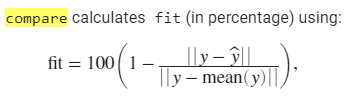

### Giunto 1

if (joint1)
    % Quantificazione bontà del fitting (il range frequenziale è lo stesso
    % di quello usato per l'identificazione - [w_inf;w_sup])
    val_points_joint1 = reshape(abs(freq_resp_valid_joint1.ResponseData),1,[]);
    modelC_points_joint1 = reshape(abs(freqresp(modelC_joint1,freq_resp_valid_joint1.Frequency)),1,[]);
    modelD_points_joint1 = reshape(abs(freqresp(modelD_joint1,freq_resp_valid_joint1.Frequency)),1,[]);

    fitC_joint1 = compute_fit_goodness(val_points_joint1,modelC_points_joint1, ...
                                       freq_resp_valid_joint1.Frequency,w_inf,w_sup);
    fitD_joint1 = compute_fit_goodness(val_points_joint1,modelD_points_joint1, ...
                                       freq_resp_valid_joint1.Frequency,w_inf,w_sup);

    % Plot modelli e dati di validazione
    fig_j1 = figure;
    h = bodeplot(freq_resp_valid_joint1,'-.',bode_opts);         % diagramma di Bode dati sperimentali
    hold on
    showConfidence(h,3)
    bode(modelC_joint1,modelD_joint1,bode_opts)             % diagramma di bode dei modelli stimati
    
    % Range frequenze investigate
    plot(w0_sin*[1 1],ylim,'-.r'); plot(w1_sin*[1 1],ylim,'-.r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    
    grid on
    hold off
    legend({'Validazione',strcat("Modello continuo (fitness = ",sprintf("%.2f",fitC_joint1),"%)"), ...
           strcat("Modello discreto  (fitness = ",sprintf("%.2f",fitD_joint1),"%)")}, ...
           'Location','southoutside','Orientation','vertical','FontSize',8)
    
    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Modello stimato e FRF sperimentale - Giunto 1';

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_valid_model_joint1.emf') 
end

### Giunto 2

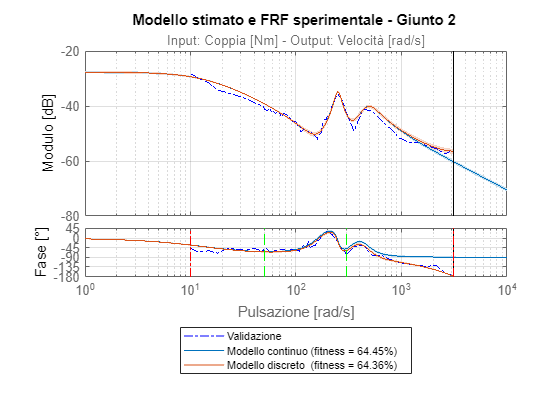

if (joint2)
    % Quantificazione bontà del fitting (il range frequenziale è lo stesso
    % di quello usato per l'identificazione - [w_inf;w_sup])
    val_points_joint2 = reshape(abs(freq_resp_valid_joint2.ResponseData),1,[]);
    modelC_points_joint2 = reshape(abs(freqresp(modelC_joint2,freq_resp_valid_joint2.Frequency)),1,[]);
    modelD_points_joint2 = reshape(abs(freqresp(modelD_joint2,freq_resp_valid_joint2.Frequency)),1,[]);

    fitC_joint2 = compute_fit_goodness(val_points_joint2,modelC_points_joint2, ...
                                       freq_resp_valid_joint2.Frequency,w_inf,w_sup);
    fitD_joint2 = compute_fit_goodness(val_points_joint2,modelD_points_joint2, ...
                                       freq_resp_valid_joint2.Frequency,w_inf,w_sup);

    % Plot modelli e dati di validazione
    fig_j2 = figure;
    h = bodeplot(freq_resp_valid_joint2,'-.',bode_opts);         % diagramma di Bode dati sperimentali
    hold on
    showConfidence(h,3)
    bode(modelC_joint2,modelD_joint2,bode_opts)             % diagramma di bode dei modelli stimati
    
    % Range frequenze investigate
    plot(w0_sin*[1 1],ylim,'-.r'); plot(w1_sin*[1 1],ylim,'-.r')
    plot(w0b_sin*[1 1],ylim,'--g'); plot(w1b_sin*[1 1],ylim,'--g')
    
    grid on
    hold off
    legend({'Validazione',strcat("Modello continuo (fitness = ",sprintf("%.2f",fitC_joint2),"%)"), ...
           strcat("Modello discreto  (fitness = ",sprintf("%.2f",fitD_joint2),"%)")}, ...
           'Location','southoutside','Orientation','vertical','FontSize',8)
    
    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Modello stimato e FRF sperimentale - Giunto 2';

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_valid_model_joint2.emf') 
end

## Salvataggio modelli validati

validatedModel.simulation = simulation;
validatedModel.joint1 = joint1;                 validatedModel.joint2 = joint2;
validatedModel.fitC_joint1 = [];                validatedModel.fitD_joint1 = [];
validatedModel.fitC_joint2 = [];                validatedModel.fitD_joint2 = [];

if (joint1)
    validatedModel.fitC_joint1 = fitC_joint1;        validatedModel.fitD_joint1 = fitD_joint1;
    
    savefig(fig_j1,strcat(modelFigDirectory,'_j1'))
end

if (joint2)
    validatedModel.fitC_joint2 = fitC_joint2;        validatedModel.fitD_joint2 = fitD_joint2;
    
    savefig(fig_j2,strcat(modelFigDirectory,'_j2'))
end

save(directoryModel_VAL,'-struct','validatedModel')